% Arda Ertanhan
% 2071519
clear all;
clc;

Load the dataset.

% Load the dataset
load('Data_Lab03.mat');

% Display information about the dataset
whos

  Name          Size             Bytes  Class     Attributes

  CT          240x62            119040  double              
  ROIs          1x31              2252  string              
  age         240x1               1920  double              
  gender      240x1               1920  double              



Calculating the mean cortical thickness for each hemisphere and visualizing the distributions using box plots.

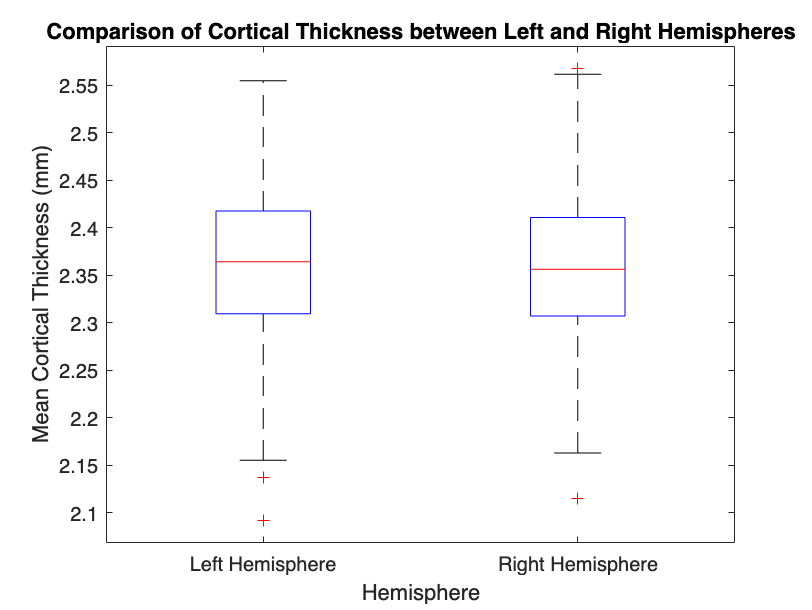

% Calculate mean cortical thickness for left and right hemispheres
mean_CT_left = mean(CT(:, 1:31), 2);  % Average across columns 1 to 31
mean_CT_right = mean(CT(:, 32:62), 2); % Average across columns 32 to 62

% Plot boxplots to compare distributions
boxplot([mean_CT_left, mean_CT_right], 'Labels', {'Left Hemisphere', 'Right Hemisphere'})
xlabel('Hemisphere')
ylabel('Mean Cortical Thickness (mm)')
title('Comparison of Cortical Thickness between Left and Right Hemispheres')

savefig('Cortical_Thickness_Hemisphere_Comparison.fig');

calculate the difference in cortical thickness between left and right hemispheres for each subject and compare these differences between male and female subjects.

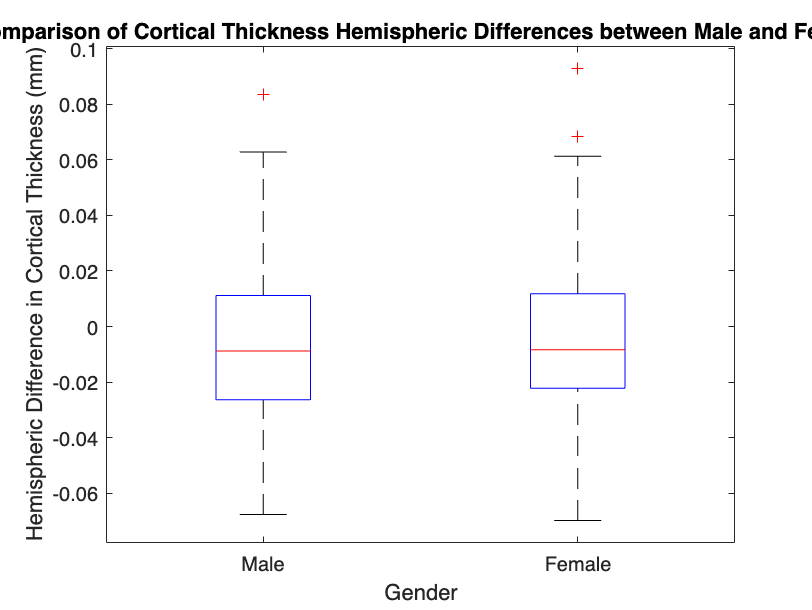

% Calculate hemispheric differences for each subject
hemispheric_diff = mean_CT_right - mean_CT_left;

% Separate hemispheric differences by gender
male_diff = hemispheric_diff(gender == 1); % Male = 1
female_diff = hemispheric_diff(gender == 2); % Female = 2

% Plot boxplots to compare differences between male and female
boxplot([male_diff, female_diff], 'Labels', {'Male', 'Female'})
xlabel('Gender')
ylabel('Hemispheric Difference in Cortical Thickness (mm)')
title('Comparison of Cortical Thickness Hemispheric Differences between Male and Female')

savefig('Cortical_Thickness_Gender_Comparison.fig');

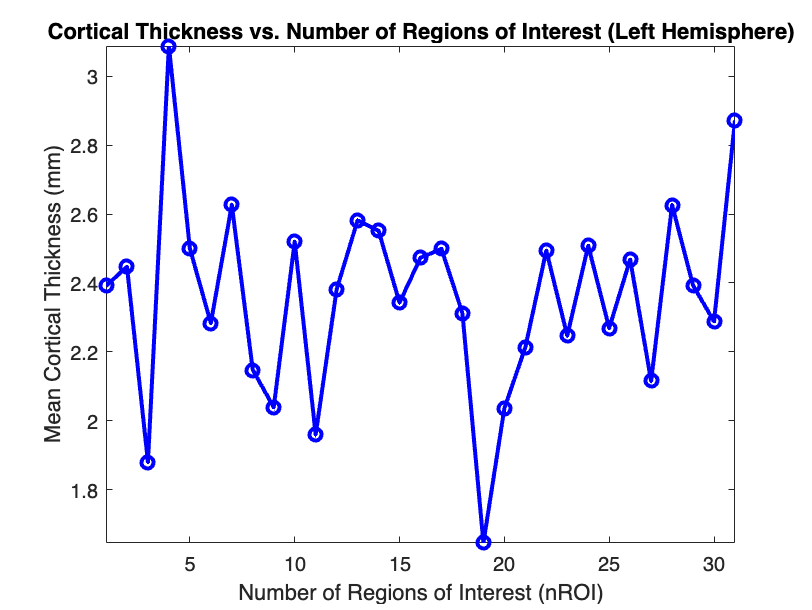

% Calculate the number of regions of interest (nROI) for each hemisphere
nROI_left = 1:31;
nROI_right = 1:31;

% Calculate mean cortical thickness for left and right hemispheres
mean_CT_left = mean(CT(:, 1:31), 1);  % Average across rows (subjects)
mean_CT_right = mean(CT(:, 32:62), 1); % Average across rows (subjects)

% Plot cortical thickness vs. nROI for left hemisphere
figure;
plot(nROI_left, mean_CT_left, 'bo-', 'LineWidth', 2);
xlabel('Number of Regions of Interest (nROI)')
ylabel('Mean Cortical Thickness (mm)')
title('Cortical Thickness vs. Number of Regions of Interest (Left Hemisphere)')
grid off; % Remove gridlines
xlim([1, 31]); % Adjust x-axis limits
ylim([min(min(mean_CT_left)), max(max(mean_CT_left))]); % Adjust y-axis limits

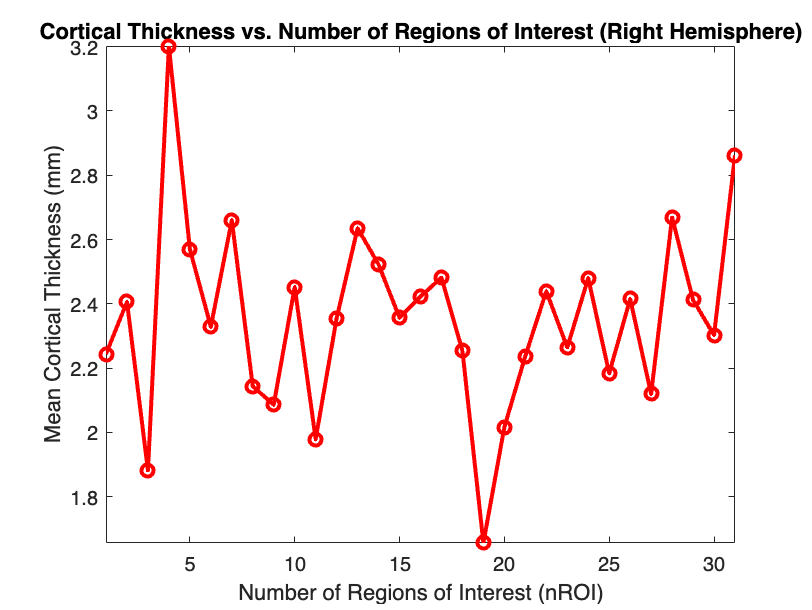


% Save the figure as a .fig file
savefig('Cortical_Thickness_vs_nROI_Left.fig');

% Plot cortical thickness vs. nROI for right hemisphere
figure;
plot(nROI_right, mean_CT_right, 'ro-', 'LineWidth', 2);
xlabel('Number of Regions of Interest (nROI)')
ylabel('Mean Cortical Thickness (mm)')
title('Cortical Thickness vs. Number of Regions of Interest (Right Hemisphere)')
grid off; % Remove gridlines
xlim([1, 31]); % Adjust x-axis limits
ylim([min(min(mean_CT_right)), max(max(mean_CT_right))]); % Adjust y-axis limits


% Save the figure as a .fig file
savefig('Cortical_Thickness_vs_nROI_Right.fig');


% Calculate mean cortical thickness for each subject
mean_CT = mean(CT, 2);

% Define bubble size based on mean cortical thickness
bubble_size = 50 * mean_CT;

% Plot cortical thickness vs. age in a bubble chart
figure;
hold on;
for g = unique(gender)'
    idx = find(gender == g);
    scatter(age(idx), mean_CT(idx), bubble_size(idx), 'filled', ...
        'MarkerFaceColor', ['b', 'r'](g), 'DisplayName', ['Male', 'Female'](g));

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

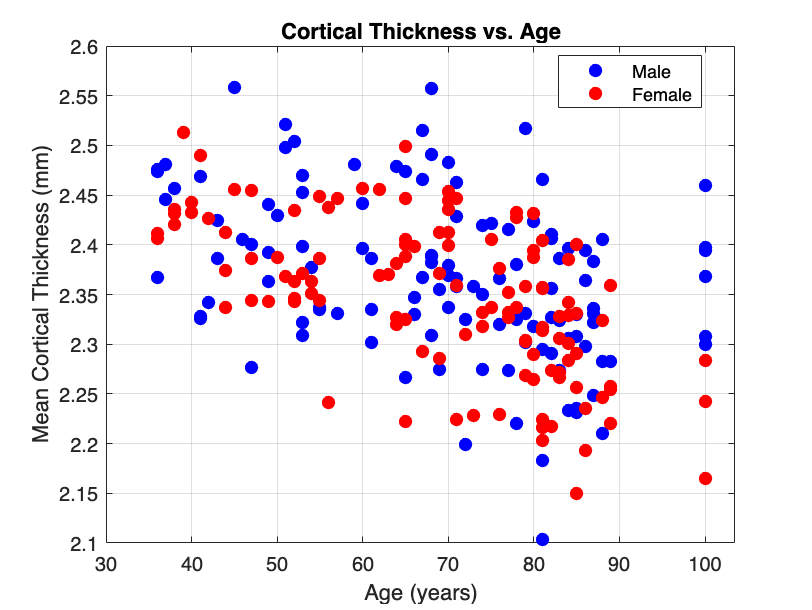

Unrecognized property 'SizeData' for class 'matlab.graphics.chart.primitive.Line'.

end
hold off;
xlabel('Age (years)')
ylabel('Mean Cortical Thickness (mm)')
title('Cortical Thickness vs. Age')
legend('Male', 'Female')
grid on;

% Save the figure as a .fig file
savefig('Cortical_Thickness_vs_Age_BubbleChart.fig');